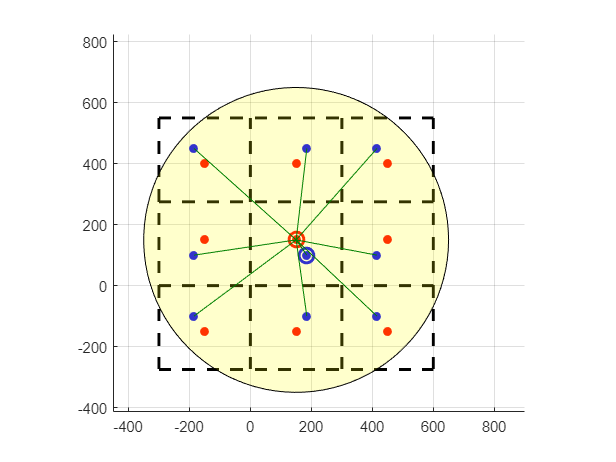

clear
TEST = 2;

switch TEST
	case 1
		dim = [3 2];		%	[width height]	(1 - 1250)
		pos0 = [1 1];		%	[x y]			(1 - (width,height-1))
		pos1 = [2 1];		%	[x y]			(1 - (width,height-1))
		max_dist = 4;

	case 2
		dim = [300 275];		%	[width height]	(1 - 1250)
		pos0 = [150 150];		%	[x y]			(1 - (width,height-1))
		pos1 = [185 100];		%	[x y]			(1 - (width,height-1))
		max_dist = 500;
end
PlotData(dim, pos0, pos1, max_dist);

%	Extract parameters
width = dim(1);
height = dim(2);
x0 = pos0(1);
y0 = pos0(2);
x1 = pos1(1);
y1 = pos1(2);

%	Find maximum replication index
%		This overcalculates, but gaurantees we get all points
nmax = floor(.5*(max_dist + 2*pos0)./dim);

%	Get all reflected positions
POS0 = GetPositions(nmax, dim, pos0, pos0, max_dist);
POS1 = GetPositions(nmax, dim, pos1, pos0, max_dist);

%	Get distances
[delta0, d20, ind0] = GetDistances(POS0, pos0, max_dist);
[delta1, d21, ind1] = GetDistances(POS1, pos0, max_dist);

%	Get inidces which don't shoot myself
%		Could use y/x or atan2(y,x) which is faster but converts to double
%		precision, which will require a tolerance setting
ind = ~any(((delta0(:, 2).*Row(delta1(:, 1)))==(delta0(:, 1).*Row(delta1(:, 2)))) ...
	& (sign(delta0(:, 1))==sign(Row(delta1(:, 1)))) & (sign(delta0(:, 2))==sign(Row(delta1(:, 2)))) ...
	& (d20<=Row(d21)), 1);

N = NumberUnique(delta1(ind, 1), delta1(ind, 2))

N = 9

function POS = GetPositions(nmax, dim, pos, pos0, max_dist)
%	Generate array of positions
x = 2*(-nmax(1):nmax(1))*dim(1) + [-1; 1].*pos(1);
y = 2*(-nmax(2):nmax(2))*dim(2) + [-1; 1].*pos(2);

%	Turn arrays into meshgrids where x'-x0<=d and y'-y0<=d
x = Row(x(abs(x-pos0(1))<=max_dist));
y = Column(y(abs(y-pos(2))<=max_dist));
[x, y] = meshgrid(x, y);
POS = [Column(x) Column(y)];
end

function [delta, d2, ind] = GetDistances(POS, pos0, max_dist)
delta = POS - pos0;
d2 = sum(delta.^2, 2);

ind = (d2<=max_dist^2) & (d2>0);
delta = delta(ind, :);
d2 = d2(ind);
end

function N = NumberUnique(dx1, dy1)
n = 1:length(dx1);
dx2 = Row(dx1);
dy2 = Row(dy1);
N = sum(~any( ...
	(dy1.*dx2==dx1.*dy2) ...									%	y1/x1==y2/x2
	& (sign(dy1)==sign(dy2)) & (sign(dx1)==sign(dx2)) ...		%	check same quadrant
	& (n.'>n), 1));												%	upper-triangular matrix only
end

function PlotData(dim, pos0, pos1, max_dist)
width = dim(1);
height = dim(2);
x0 = pos0(1);
y0 = pos0(2);
x1 = pos1(1);
y1 = pos1(2);
 
nmax = ceil((max_dist + pos0)./(2*dim));

%	Index locations
nx = (-nmax(1):nmax(1)).';
ny = (-nmax(2):nmax(2)).';

%	My positions
X0 = Column(2*nx*width + [1 -1]*x0);
Y0 = Column(2*ny*height + [1 -1]*y0);

%	Trainer positions
X1 = Column(2*nx*width + [1 -1]*x1);
Y1 = Column(2*ny*height + [1 -1]*y1);

indx = (abs(X0-x0)<=max_dist) & (abs(X1-x0)<=max_dist);
indy = (abs(Y0-y0)<=max_dist) & (abs(Y1-y0)<=max_dist);
X0 = X0(indx);
X1 = X1(indx);
Y0 = Y0(indy);
Y1 = Y1(indy);

%	Create full co-ordinates
[X0, Y0] = meshgrid(X0.', Y0);
X0 = Column(X0);
Y0 = Column(Y0);

[X1, Y1] = meshgrid(X1.', Y1);
X1 = Column(X1);
Y1 = Column(Y1);

fig = gcf;
clf(fig);
ax = axes(fig);

%	Plot rooms
xmin = min(min(X0), min(X1));
xmax = max(max(X0), max(X1));
ymin = min(min(Y0), min(Y1));
ymax = min(max(Y0), max(Y1));
nxmin = floor(xmin/width);
nxmax = ceil(xmax/width);
nymin = floor(ymin/height);
nymax = ceil(ymax/height);

line(repmat(width*[nxmin; nxmax], [1 nymax-nymin+1]), [1; 1].*(nymin:nymax)*height, ...
	"LineStyle", "--", "Color", "k", "LineWidth", 2);
line([1; 1].*(nxmin:nxmax)*width, repmat(height*[nymin; nymax], [1 nxmax-nxmin+1]), ...
	"LineStyle", "--", "Color", "k", "LineWidth", 2);

%	Replicated my positions
line(X0, Y0, ...
	"Color", "None", "MarkerFaceColor", "r", "Marker", "o");

%	Replicated trainer positions
line(X1, Y1, ...
	"Color", "None", "MarkerFaceColor", "b", "Marker", "o");

%	My position
line(pos0(1), pos0(2), "Color", "r", "Marker", "o", "MarkerSize", 10, "LineWidth", 2);

%	Trainer position
line(pos1(1), pos1(2), "Color", "b", "Marker", "o", "MarkerSize", 10, "LineWidth", 2);

%	Max distance
th = linspace(0, 2*pi, 100).';
patch(x0+max_dist*cos(th), x0+max_dist*sin(th), "y", "FaceAlpha", .2);

%	Plot all directions
line(x0+[0; 1].*Row(X1-x0), y0+[0; 1].*Row(Y1-y0), ...
	"Color", [0 .5 0]);

grid on;
axis equal;
xlim(1.5*width*[nxmin nxmax]);
ylim(1.5*height*[nymin nymax]);
end

function x = Column(x) 
x = x(:);
end

function x = Row(x) 
x = reshape(x, 1, []);
end

function x = Plane(x) 
x = reshape(x, 1, 1, []);
end
